# Train Convolutional Neural Network for Regression

## Load Data

% imfilelist = dir('testSet/*.png');
UnPhi = load('testSet/Un_Phi.out')';

imgSz = 48;
Nimgs = 550000;

images = single(zeros(imgSz,imgSz,1,Nimgs));
for i=1:Nimgs
    images(:,:,1,i) = imread(sprintf('testSet/image_%d.png', i));
%     images(:,:,1,i) = imbinarize(images(:,:,1,i), 90);
    if(mod(i, 10000) == 0)
        i
    end
end
UnPhi = single(UnPhi(1:Nimgs,:));
save('xy_bin_5e5.mat','-mat','images','UnPhi','-v7.3');

load('xy_bin_5e5.mat');
imgSz = 48;

XTrain = images(:,:,:,1:500000);
YTrain = UnPhi(1:500000,:);

[YTrain,mu,sigma] = zscore(YTrain);

XValidation = images(:,:,:,500000:end);
YValidation = UnPhi(500000:end,:);
YValidation(:,1) = (YValidation(:,1) - mu(1))./sigma(1);
YValidation(:,2) = (YValidation(:,2) - mu(2))./sigma(2);

images = [];

Display 20 random training images using `imshow`.

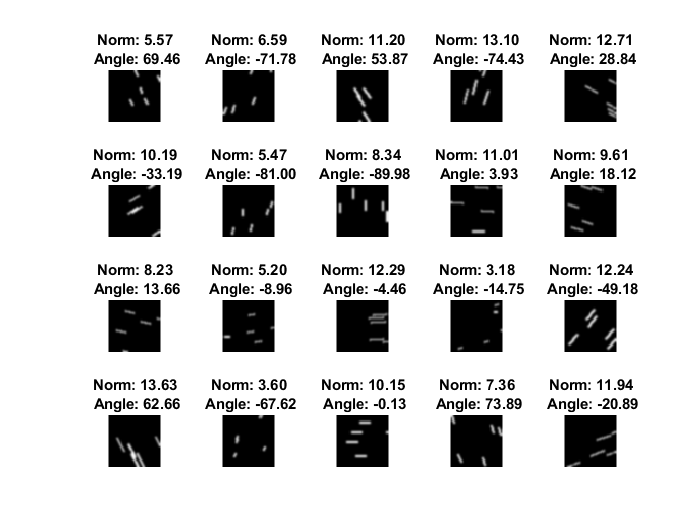

numTrainImages = length(YTrain);
figure;
idx = randperm(numTrainImages,20);
for i = 1:length(idx)
    subplot(4,5,i)    
    imshow(squeeze(XTrain(:,:,1,idx(i))),[0 255])
    title(sprintf('Norm: %.2f\n Angle: %.2f', ... 
          YTrain(idx(i),1)*sigma(1) + mu(1), YTrain(idx(i),2)*sigma(2) + mu(2)));
    drawnow
end


## Check Data Normalization

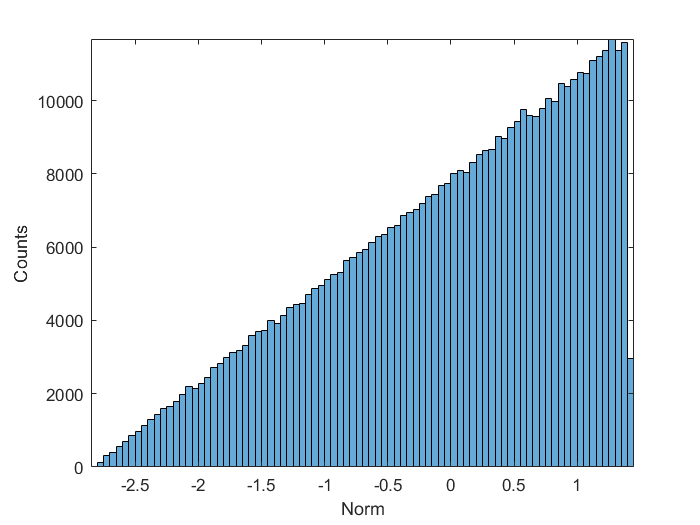

figure
histogram(YTrain(:,1))
axis tight
ylabel('Counts')
xlabel('Norm')

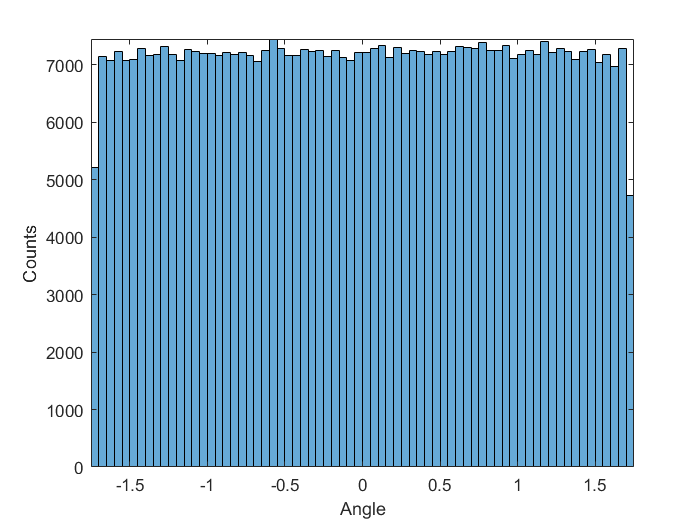

figure
histogram(YTrain(:,2))
axis tight
ylabel('Counts')
xlabel('Angle')

If the distribution of the input or response is very uneven or skewed, you can also perform nonlinear transformations (for example, taking logarithms) to the data before training the network.

## Create Network Layers

To solve the regression problem, create the layers of the network and include a regression layer at the end of the network.

The first layer defines the size and type of the input data. The input images are 28-by-28-by-1. Create an image input layer of the same size as the training images.

The middle layers of the network define the core architecture of the network, where most of the computation and learning take place.

The final layers define the size and type of output data. For regression problems, a fully connected layer must precede the regression layer at the end of the network. Create a fully connected output layer of size 1 and a regression layer.

Combine all the layers together in a `Layer` array.

layers = [
    imageInputLayer([imgSz imgSz 1])

    convolution2dLayer(5,8,'Padding','same')
    batchNormalizationLayer
    reluLayer
    
    averagePooling2dLayer(2,'Stride',2)

    convolution2dLayer(5,16,'Padding','same')
    batchNormalizationLayer
    reluLayer
    
    averagePooling2dLayer(2,'Stride',2)
  
    convolution2dLayer(5,32,'Padding','same')
    batchNormalizationLayer
    reluLayer
    
    averagePooling2dLayer(2,'Stride',2)
    
    convolution2dLayer(5,32,'Padding','same')
    batchNormalizationLayer
    reluLayer
    
    dropoutLayer(0.2)
    fullyConnectedLayer(2)
    regressionLayer];

## Train Network

Create the network training options. Train for 30 epochs. Set the initial learn rate to 0.001 and lower the learning rate after 20 epochs. Monitor the network accuracy during training by specifying validation data and validation frequency. The software trains the network on the training data and calculates the accuracy on the validation data at regular intervals during training. The validation data is not used to update the network weights. Turn on the training progress plot, and turn off the command window output.

miniBatchSize  = 192;
validationFrequency = floor(length(YTrain)/miniBatchSize);
options = trainingOptions('adam', ...
    'MiniBatchSize',miniBatchSize, ...
    'MaxEpochs',150, ...
    'InitialLearnRate',2e-4, ...
    'LearnRateSchedule','piecewise', ...
    'LearnRateDropFactor',0.5, ...
    'LearnRateDropPeriod',50, ...
    'Shuffle','every-epoch', ...
    'ValidationData',{XValidation,YValidation}, ...
    'ValidationFrequency',validationFrequency, ...
    'Plots','training-progress', ...
    'Verbose',false,...
    'L2Regularization',0);

Create the network using `trainNetwork`. This command uses a compatible GPU if available. Otherwise, `trainNetwork` uses the CPU. A CUDA® enabled NVIDIA® GPU with compute capability 3.0 or higher is required for training on a GPU. 

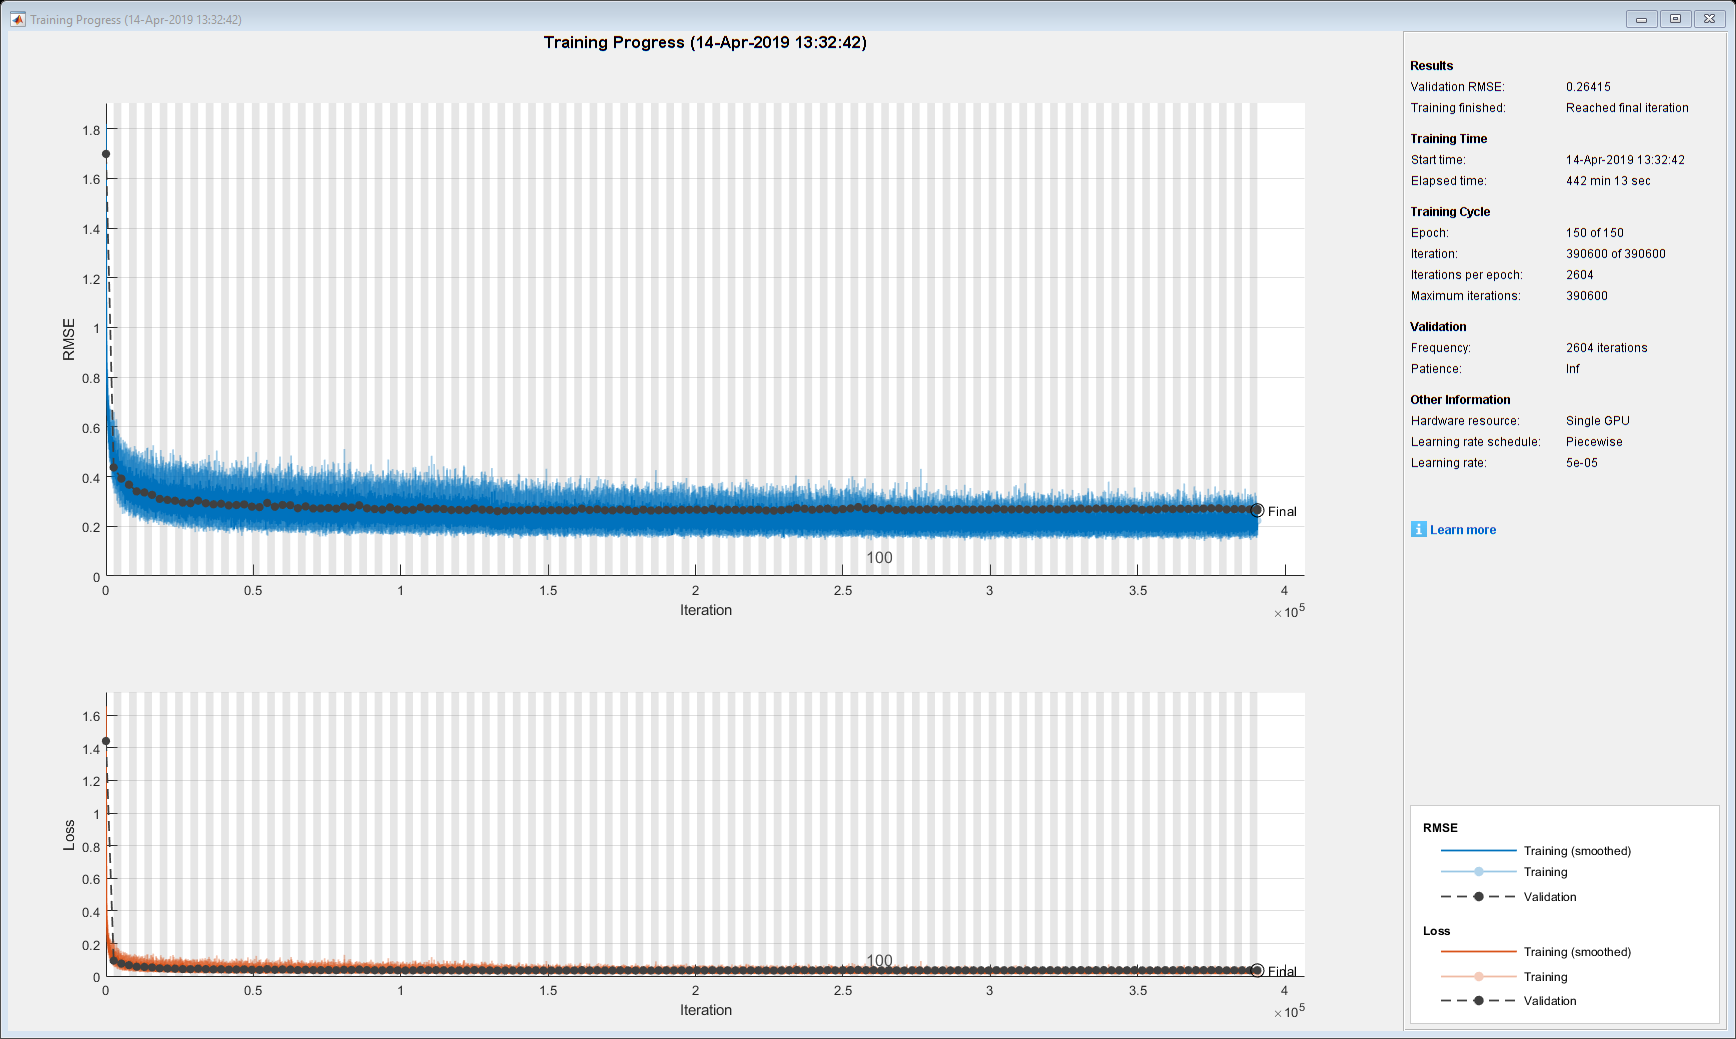

[net,traininfo] = trainNetwork(XTrain,YTrain,layers,options);

Examine the details of the network architecture contained in the `Layers` property of `net`.

net.Layers

ans =   18x1 Layer array with layers:

     1   'imageinput'         Image Input           48x48x1 images with 'zerocenter' normalization
     2   'conv_1'             Convolution           8 5x5x1 convolutions with stride [1  1] and padding 'same'
     3   'batchnorm_1'        Batch Normalization   Batch normalization with 8 channels
     4   'relu_1'             ReLU                  ReLU
     5   'maxpool_1'          Max Pooling           2x2 max pooling with stride [2  2] and padding [0  0  0  0]
     6   'conv_2'             Convolution           16 5x5x8 convolutions with stride [1  1] and padding 'same'
     7   'batchnorm_2'        Batch Normalization   Batch normalization with 16 channels
     8   'relu_2'             ReLU                  ReLU
     9   'maxpool_2'          Max Pooling           2x2 max pooling with stride [2  2] and padding [0  0  0  0]
    10   'conv_3'             Convolution      

## Test Network

Test the performance of the network by evaluating the accuracy on the validation data.

Use `predict` to predict the angles of rotation of the validation images.

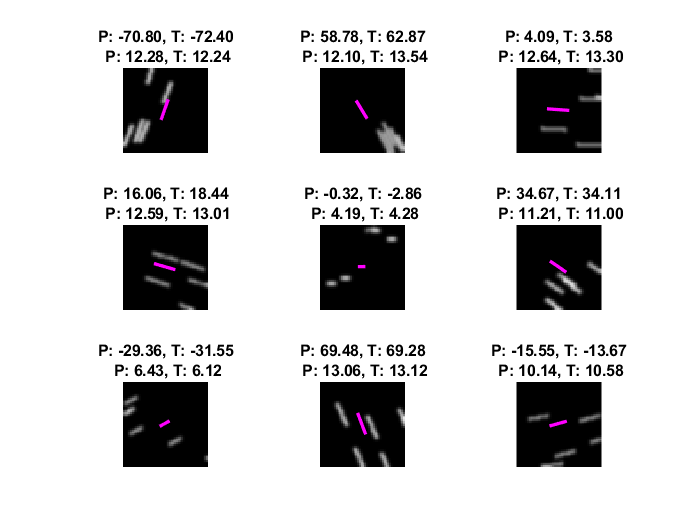

YPredicted = predict(net,XValidation);

angle_idx = 2;
predictedNorm = YPredicted(:,1)*sigma(1) + mu(1);
predictedPhi = YPredicted(:,2)*sigma(2) + mu(2);
truePhi = YValidation(:,2)*sigma(2) + mu(2);
trueNorm = YValidation(:,1)*sigma(1) + mu(1);

numTrainImages = length(YPredicted);
figure;
idx = randperm(numTrainImages,9);
for i = 1:length(idx)
    subplot(3,3,i)    
    imshow(squeeze(XValidation(:,:,1,idx(i))),[0 255])
    
    x0 = imgSz/2;
    y0 = imgSz/2;
    
    x1 = x0 + cosd(predictedPhi(idx(i)))*predictedNorm(idx(i))/2;
    y1 = y0 + sind(predictedPhi(idx(i)))*predictedNorm(idx(i))/2;
    
    hold all;
    line([x0,x1],[y0,y1],'Color','m','LineWidth',2);
    
    x1 = x0 - cosd(predictedPhi(idx(i)))*predictedNorm(idx(i))/2;
    y1 = y0 - sind(predictedPhi(idx(i)))*predictedNorm(idx(i))/2;
    
    line([x0,x1],[y0,y1],'Color','m','LineWidth',2);
    
    title(sprintf('P: %.2f, T: %.2f\n P: %.2f, T: %.2f', ... 
          predictedPhi(idx(i)), truePhi(idx(i)), ...
          predictedNorm(idx(i)), trueNorm(idx(i))));
    drawnow
end

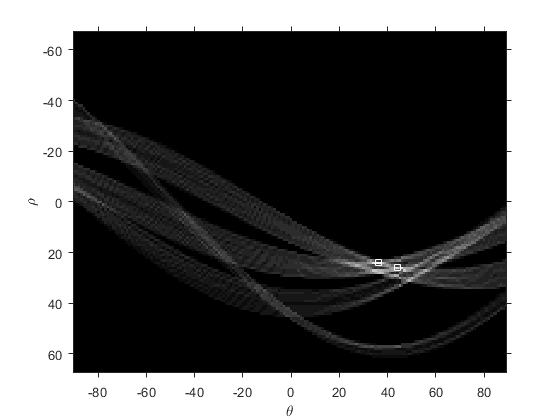

ii=randi(length(YValidation));
im = squeeze(XValidation(:,:,1,ii));
BW = edge(im,'canny');
dTheta = 1;
angles = -90:dTheta:89;
[H,T,R] = hough(BW,'RhoResolution',1,'Theta',angles);
P  = houghpeaks(H,2);
figure;
imshow(H,[],'XData',T,'YData',R,'InitialMagnification','fit');
xlabel('\theta'), ylabel('\rho');
axis on, axis normal, hold on;
plot(T(P(:,2)),R(P(:,1)),'s','color','white');

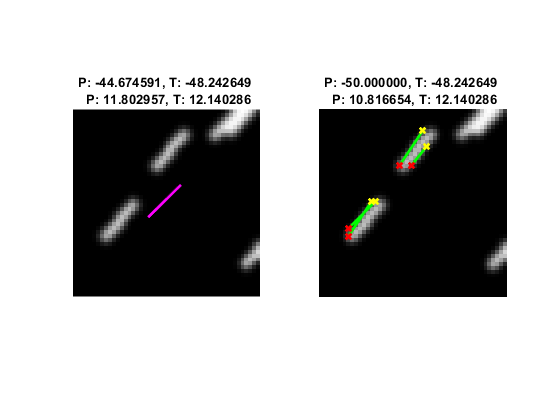

lines = houghlines(BW,T,R,P,'FillGap',2,'MinLength',4);
figure; 
subplot(1,2,1);
imshow(im, [0 255]), hold on
x0 = imgSz/2;
y0 = imgSz/2;    
x1 = x0 + cosd(predictedPhi(ii))*predictedNorm(ii)/2;
y1 = y0 + sind(predictedPhi(ii))*predictedNorm(ii)/2;
hold all;
line([x0,x1],[y0,y1],'Color','m','LineWidth',2);
x1 = x0 - cosd(predictedPhi(ii))*predictedNorm(ii)/2;
y1 = y0 - sind(predictedPhi(ii))*predictedNorm(ii)/2;
line([x0,x1],[y0,y1],'Color','m','LineWidth',2);
    
title(sprintf('P: %f, T: %f \n P: %f, T: %f', predictedPhi(ii), truePhi(ii), predictedNorm(ii), trueNorm(ii)));
subplot(1,2,2);
imshow(im, [0 255]), hold on
hough_angle = -90+mean(angles(P(1:2,2)));
% if(hough_angle < -90)
%     hough_angle = 180 - hough_angle;
% elseif(hough_angle > 90)
%     hough_angle = 180 - hough_angle;
% end
max_len = 0;
for k = 1:length(lines)
   xy = [lines(k).point1; lines(k).point2];
   plot(xy(:,1),xy(:,2),'LineWidth',2,'Color','green');

   % Plot beginnings and ends of lines
   plot(xy(1,1),xy(1,2),'x','LineWidth',2,'Color','yellow');
   plot(xy(2,1),xy(2,2),'x','LineWidth',2,'Color','red');

   % Determine the endpoints of the longest line segment
   len = norm(lines(k).point1 - lines(k).point2);
   if ( len > max_len)
      max_len = len;
      xy_long = xy;
   end
end
title(sprintf('P: %f, T: %f \n P: %f, T: %f',hough_angle, truePhi(ii), max_len, trueNorm(ii)))

**Evaluate Performance**

Evaluate the performance of the model by calculating:

- The percentage of predictions within an acceptable error margin

- The root-mean-square error (RMSE) of the predicted and actual angles of rotation

Calculate the prediction error between the predicted and actual angles of rotation.

predictionErrorNorm = (YValidation(:,1) - YPredicted(:,1))*sigma(1);
predictionErrorPhi = (YValidation(:,2) - YPredicted(:,2))*sigma(2);

numValidationImages = length(YValidation);

thrNorm = 1;
thrPhi = 18; 
numCorrectNorm = sum(abs(predictionErrorNorm) < thrNorm);
numCorrectPhi = sum(abs(predictionErrorPhi) < thrPhi);

accuracy = [numCorrectNorm numCorrectPhi]/numValidationImages

accuracy =     0.9642    0.9639


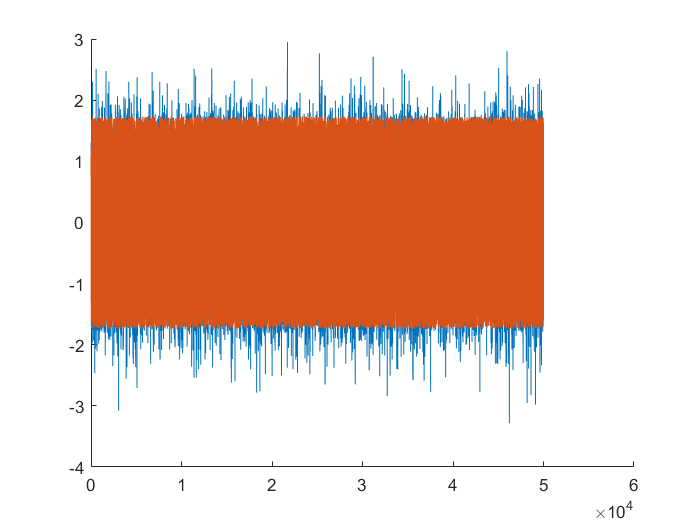

clf
hold all
plot(YPredicted(:,2))
plot(YValidation(:,2));

Use the root-mean-square error (RMSE) to measure the differences between the predicted and actual angles of rotation.

squares = [predictionErrorNorm.^2 predictionErrorPhi.^2];
rmse = sqrt(mean(squares))

rmse = 1×2 single row vector
    0.4687   11.8522


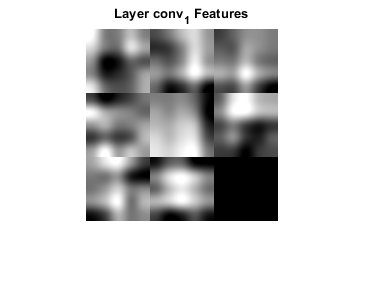

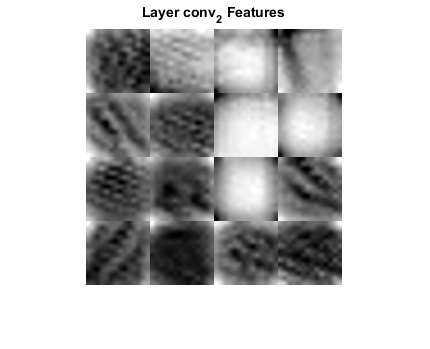

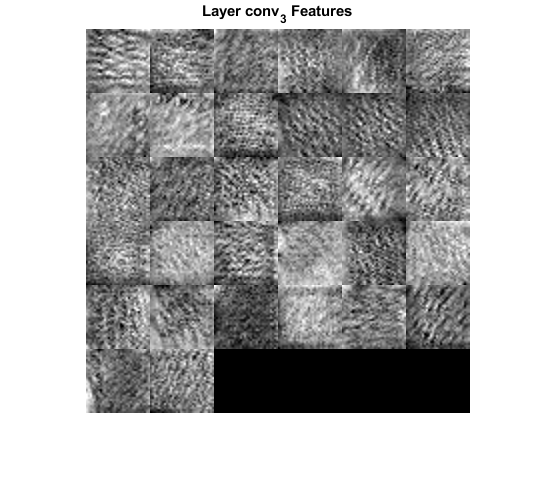

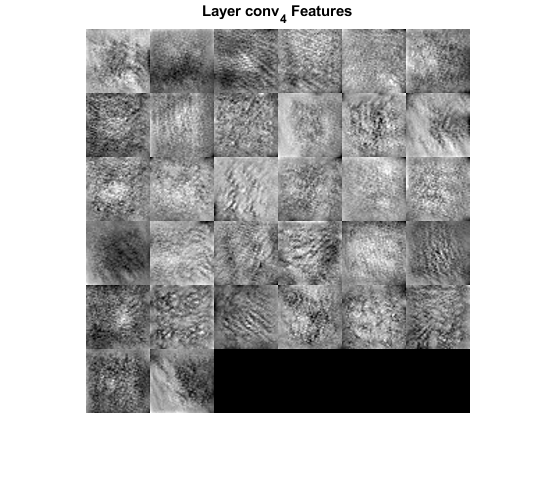

layers = [2 6 10 13];

for layer = layers
    I = deepDreamImage(net,layer,1:net.Layers(layer).NumFilters, ...
        'Verbose',false, ...
        'PyramidLevels',1);
    
    figure
    I = imtile(I,'ThumbnailSize',[64 64]);
    imshow(I)
    name = net.Layers(layer).Name;
    title(['Layer ',name,' Features'])
end

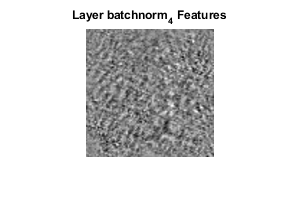

fc_layer = 14;
I = deepDreamImage(net,fc_layer,1, ...
    'Verbose',false, ...
    'NumIterations',50);
figure
I = imtile(I,'ThumbnailSize',[128 128]);
imshow(I)
name = net.Layers(fc_layer).Name;
title(['Layer ',name,' Features'])

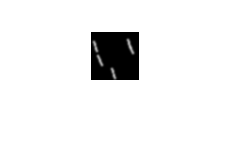

ii=randi(length(YValidation));
im = squeeze(XValidation(:,:,1,ii));

layers = [2 6 10 14];

figure;
imshow(im, [0 255])

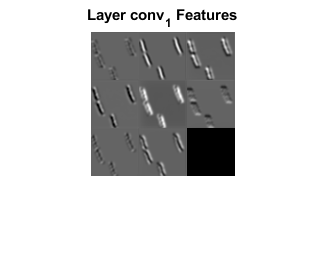

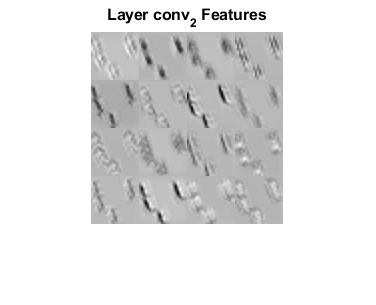

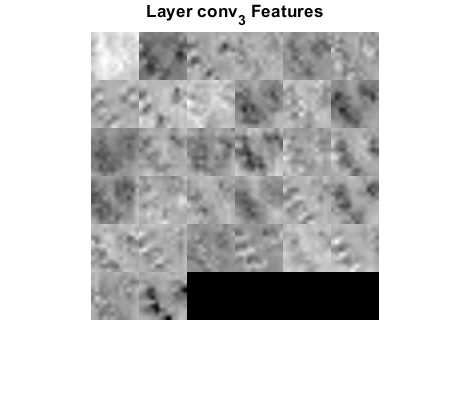

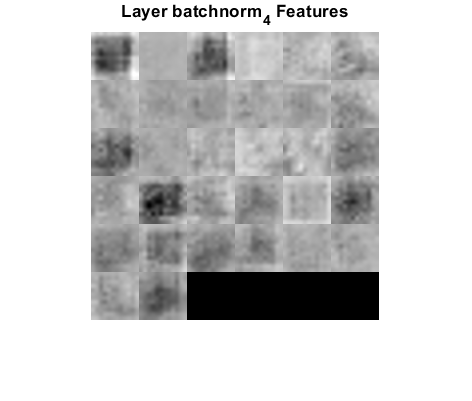

for layer = layers
    act1 = activations(net,im,layer);
    sz = size(act1);
    act1 = reshape(act1,[sz(1) sz(2) 1 sz(3)]);

    figure;
    I = imtile(mat2gray(act1),'ThumbnailSize',[48 48]);
    imshow(I)
    name = net.Layers(layer).Name;
    title(['Layer ',name,' Features'])
end

analyzeNetwork(net.Layers)

fname = 'streakImage_density20_imageSize960_partRadius4';
image_dns = imread(sprintf('DATASETfromDNS/%s.png',fname));

windowSz = 48;
step = 24;
start = windowSz/2;

dTheta = 1;
angles = -90:dTheta:89;

Un_phi_ANN = [];
Un_phi_hough = [];
x0 = [];
y0 = [];
x1 = [];
y1 = [];
x0_hough = [];
x1_hough = [];
y0_hough = [];
y1_hough = [];

window_images = single(zeros([imgSz imgSz 1 (size(image_dns,1)/step - 1)^2]));

idx = 1;
for i=start:step:(size(image_dns,1)-windowSz/2)
    for j=start:step:(size(image_dns,2)-windowSz/2)
        img_window = image_dns(i-windowSz/2+1:i+windowSz/2,j-windowSz/2+1:j+windowSz/2);
        window_images(:,:,1,idx) = img_window;
        
        % CNN
        Un_phi_ANN(idx,3:4) = predict(net, img_window).*sigma + mu;

        xc = j;
        yc = i;    
        Un_phi_ANN(idx,1:2) = [xc yc];
        
        x0(idx) = xc + cosd(Un_phi_ANN(idx,4))*Un_phi_ANN(idx,3) / 2;
        y0(idx) = yc + sind(Un_phi_ANN(idx,4))*Un_phi_ANN(idx,3) / 2;
        x1(idx) = xc - cosd(Un_phi_ANN(idx,4))*Un_phi_ANN(idx,3) / 2;
        y1(idx) = yc - sind(Un_phi_ANN(idx,4))*Un_phi_ANN(idx,3) / 2;
        
        % Hough transform
        BW = edge(img_window,'canny');
        [H,T,R] = hough(BW,'RhoResolution',1,'Theta',angles);
        P  = houghpeaks(H,2);
        lines = houghlines(BW,T,R,P,'FillGap',2,'MinLength',4);
        
        max_len = 0;
        for k = 1:length(lines)
            len = norm(lines(k).point1 - lines(k).point2);
            if ( len > max_len)
                max_len = len;
            end
        end
        
        hough_angle = -90+mean(angles(P(1:2,2)));
        
        Un_phi_hough(idx,:) = [xc yc max_len hough_angle];
        
        x0_hough(idx) = xc + cosd(hough_angle)*max_len / 2;
        y0_hough(idx) = yc + sind(hough_angle)*max_len / 2;
        x1_hough(idx) = xc - cosd(hough_angle)*max_len / 2;
        y1_hough(idx) = yc - sind(hough_angle)*max_len / 2;
        idx = idx + 1;
    end
end

Un_phi_ANN = double(Un_phi_ANN);
save([fname '_CNN.txt'],'Un_phi_ANN','-ascii');
save([fname '_Hough.txt'],'Un_phi_hough','-ascii');

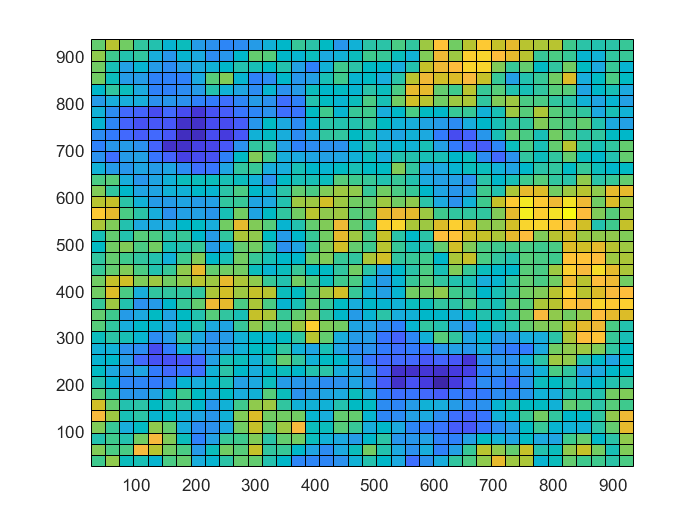

figure
subplot(1,2,1)

imshow(image_dns)
title('CNN')
axis on
hold all
line([x0; x1],[y0; y1],'Color','y','LineWidth',1);
set(gca,'YDir','reverse')
axis tight
axis equal
subplot(1,2,2)
imshow(image_dns)
title('Hough');
axis on
hold all
line([x0_hough; x1_hough],[y0_hough; y1_hough],'Color','y','LineWidth',1);
set(gca,'YDir','reverse')
axis tight
axis equal

print('-dpng','-r300', [fname '_CNN_vs_Hough_PIV.png']); crop_png([fname '_CNN_vs_Hough_PIV.png']);

figure;
pcolor(reshape(Un_phi_ANN(:,1), [39 39]), reshape(Un_phi_ANN(:,2), [39 39]), reshape(Un_phi_ANN(:,3), [39 39]))